# Computation of hypothesis testing on the LongEval submission

## Setup

Load the performance score about the runs. The file contains:

- `ap`: a matrix where rows are topics and columns are runs; each cell contains the AP score for a run on a given topic;

- `runs`: an array of strings containing the identifiers of the runs; elements in the array are in the same order as columns on ap;

- `topics`: an array of strings containing the identifiers of the topics; elements in the array are in the same order as rows on ap;

% Load Average Precision data
% Other measures available are: P@10, nDCG, RBP
load data/ap.mat

% rename ap into measure to make follow-up processing the same for whatever
% measure we load
measure = ap;

% remove the now useless ap matrix
clear ap;

% convert cell values to string
runs = string(runs);

% the significance level
alpha = 0.05;

## Box Plot

Show the box plot of the runs.

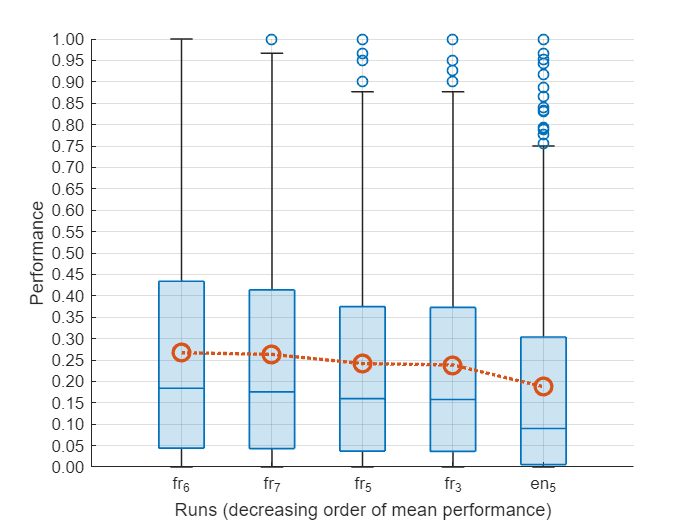

% Compute the mean performance of each run across topics
% This is the MAP for each run, if we loaded the AP data
mean_values = mean(measure);

% sort in descending order of mean score
[mean_values, idx] = sort(mean_values, 'descend');

% re-order runs by descending mean of the measure
% needed to have a more nice looking box plot
measure = measure(:, idx);
runs = runs(idx);

figure

% show the box plot
boxchart(measure)

% show grid in plots
grid on;

hold on

% plot the mean on top of the box plot
plot (mean_values, ':o', "MarkerSize", 10, "LineWidth", 2)

%{
% plot the value of the means
str_mean = strtrim(cellstr(num2str([mean_values(:)],'%.3f')));
text ((1:numel(runs)) + 0.1, mean_values, str_mean,'VerticalAlignment','bottom','Color','#D95319');

% plot the value of the medians
median_values = median(measure);
str_median = strtrim(cellstr(num2str([median_values(:)],'%.3f')));
text ((1:numel(runs)) + 0.1, median_values, str_median,'VerticalAlignment','bottom','Color','#0072BD');
%}

% adjust tick labels on x-axis
ax = gca;
ax.XTickLabel = runs;
ax.YTick = 0:0.05:1;
ytickformat('%.2f')

xlabel("Runs (decreasing order of mean performance)")
ylabel("Performance")

## Two-way ANOVA

Compute the two-way ANOVA

% perform the ANOVA
[~, tbl, sts] = anova2(measure, 1, 'off');

% display the ANOVA table
tbl

tbl = 5×6 cell array
    {'Source' }    {'SS'      }    {'df'  }    {'MS'      }    {'F'       }    {'Prob>F'    }
    {'Columns'}    {[  2.6968]}    {[   4]}    {[  0.6742]}    {[ 46.0411]}    {[1.8275e-37]}
    {'Rows'   }    {[172.9451]}    {[ 671]}    {[  0.2577]}    {[ 17.6013]}    {[         0]}
    {'Error'  }    {[ 39.3028]}    {[2684]}    {[  0.0146]}    {0×0 double}    {0×0 double  }
    {'Total'  }    {[214.9447]}    {[3359]}    {0×0 double}    {0×0 double}    {0×0 double  }


## Tukey HSD Test

Perform the multiple comparison

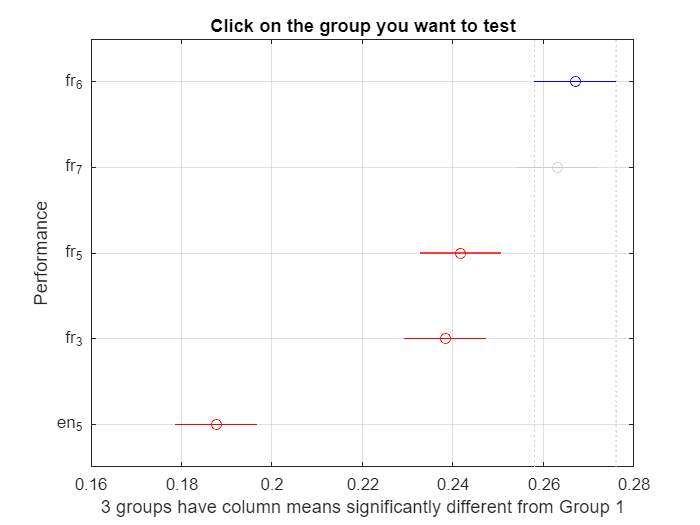

multcompare(sts, 'Alpha', alpha, 'Ctype', 'hsd');

% rename y-axis labels for readability
ax = gca;
ax.YTickLabel = flip(runs);